# 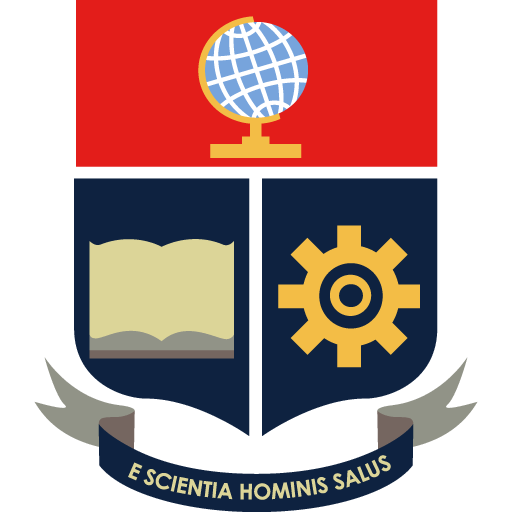Escuela Politécnica Nacional

#### `UTILIZACIÓN DEL SISTEMA DE RECONOCIMIENTO DE GESTOS EMPLEADO EN EL PROYECTO DE INVESTIGACIÓN PIGR-19-07 PARA EL COMANDO DE UN SISTEMA MULTI-AGENTE`

# Envío de comandos

- Archivo para envío de comandos de referencia para el sistema

 
%client_write
clear all
clc
global client
client= tcpclient("localhost",3000);
%Servidor abierto a cualquiera en el puerto 3100 ("0.0.0.0")
global server2
server2= tcpserver("0.0.0.0",3100);

 
open("C:\Users\Cinthy\Desktop\SoftwareReconocimientoIA\Software\GeneralHGR\Main.m")

Utilizar "Run" para empezar a ejecutar el programa una vez abierto el archivo

 %server = tcpserver("0.0.0.0",3000)
option=6;
while option~=7
clc
option=input('Comandos:\n1) WaveOut  --   Opción de Derecha\n2) WaveIn   --   Opción de Izquierda\n3) Fist     --   Seleccionar\n4) Open     --   Regresar\n5) Pinch    --   Cambio de distancia entre agentes\n6) Relax    --   Nada\nIngresar 7 para terminar el envío.\n Selección: ');
write(client,option,"uint8")
if server2.Connected~=0%necesita haber conexion para envio de datos
    write(server2,option,"uint8");%%
end
pause(0.5)
write(client,6,"uint8")
if server2.Connected~=0%necesita haber conexion para envio de datos
    write(server2,6,"uint8");%%
end
end
clc
% disp('Fin de envío de comandos')

**Opciones de comandos listadas en el menú:**

- WaveOut  --   Opción de Derecha

- WaveIn     --   Opción de Izquierda

- Fist           --   Seleccionar

- Open        --   Regresar

- Pinch        --   Cambio de distancia entre agentes

- Relax        --   Nada

- Nota: se recomienda realizar la siguiente acción una vez se ejecute, para disponer una ventana pequeña con el menú: